# Chapter 4 ATAP Exercises

## Interpolants, Projections, and Aliasing

#### Mason Mault June 2025

Exercises worked

Exercise 4.1: Node polynomial for Chebyshev points (in my BarycentricInterpolation pg 3)

Exercise 4.2: Examples of Aliasing

Exercise 4.6: Chebfun computation of truncations

Exercise 4.7: When projection equals interpolation

**Exercise 4.2: Examples of Aliasing**

On the n + 1 point Chebyshev grid (with n = 20), determine which Chebyshev polynomials $T_k \left(x\right)$ take the same values as $T_5 \left(x\right)$. Theorem 4.1 in ATAP states

For any $k\ge 0$, $T_k \left(x\right)$ takes the same value on the (n + 1) point grid as $T_m \left(x\right)$ with


$$m=|\left(k+n-1\right)\left(\textrm{mod}\;2n\right)-\left(n-1\right)|$$


a number in the range $0\le m\le n$.

n = 20;

% chebyshev grid of n+1 points
x = chebpts(n+1); 

% value of m to alias
targetM = 5;
kMax = 100;

% initialize alias list
aliasIndex = [];

% find aliases of Tm from 0 to kMax
for k = 0:kMax
    % eq 4.4, page 26 ATAP
    alias = abs(mod(k + n - 1, 2*n) - (n - 1));
    if alias == targetM
        aliasIndex(end + 1) = k;
    end
end

aliasIndex(2:end)

ans =     35    45    75    85


 The above values of k give $T_k \left(x\right)$ = $T_5 \left(x\right)$ on the 21 point Chebyshev grid.

Build these Chebyshev polynomials and demonstrate their aliasing on the 21 point grid.

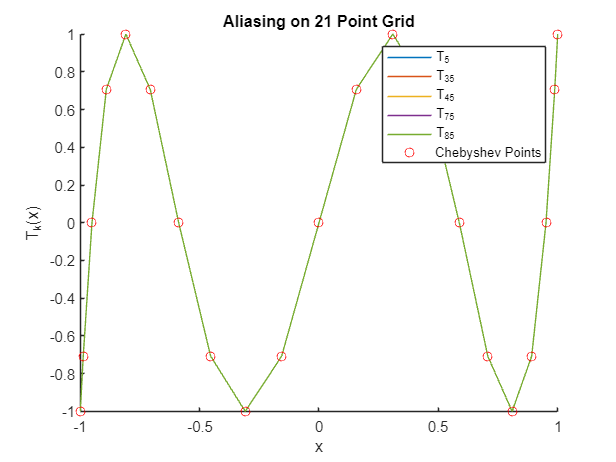

% get Chebyshev polynomials using aliasIndex
T5 = chebpoly(5);
T35 = chebpoly(35);
T45 = chebpoly(45);
T75 = chebpoly(75);
T85 = chebpoly(85);

% evaluate at Chebyshev points
y5 = T5(x);
y35 = T35(x);
y45 = T45(x);
y75 = T75(x);
y85 = T85(x);

% plot values at Chebyshev points
figure
hold on
plot(x, y5,'DisplayName', 'T_5');
plot(x, y35, 'DisplayName', 'T_{35}');
plot(x, y45, 'DisplayName', 'T_{45}');
plot(x, y75, 'DisplayName', 'T_{75}');
plot(x, y85, 'DisplayName', 'T_{85}');
plot(x, y5, 'ro', 'DisplayName', 'Chebyshev Points');
legend show
title('Aliasing on 21 Point Grid')
xlabel('x'), ylabel('T_k(x)')

**Exercise 4.6: Chebfun computation of truncations**

Build a chebfun of $f\left(x\right)=\tanh \left(4x-1\right)$ then truncate its series to $f_4 \left(x\right)$. Compare this to $p_4 \left(x\right)$ where truncation is done manually.

xx = chebfun('x');
f = tanh(4*xx - 1);
n2 = 4;
f4 = chebfun(f, 'trunc', n2 + 1);

% extract coefficients of f
a = chebcoeffs(f);
truncA = a(1:n2 + 1);
p4 = chebfun(truncA, 'coeffs');

% build p4 manually to ensure i know whats happening
p4_2 = truncA(1)*chebpoly(0) + truncA(2)*chebpoly(1) + truncA(3)*chebpoly(2) + ...
          truncA(4)*chebpoly(3) + truncA(5)*chebpoly(4);

% ensure p4 == p4_2
maxDif2 = max(abs(p4(xx) - p4_2(xx)))

maxDif2 = 0

% compare pn and p4
maxDif = max(abs(p4(xx) - p4(xx)))

maxDif = 0

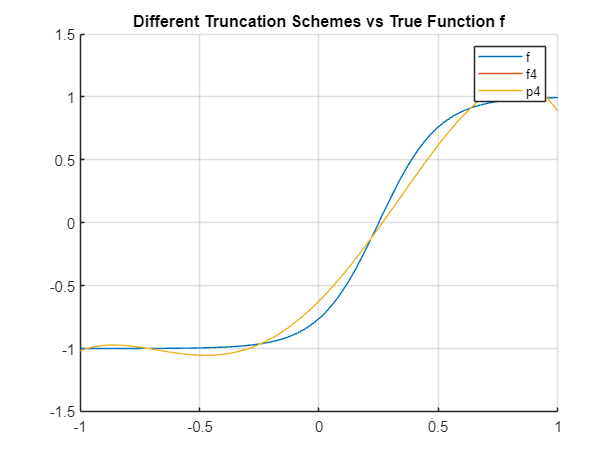

% plot f, pn, and truncF
figure
hold on
grid on
plot(f, 'DisplayName', 'f'); 
plot(f4, 'DisplayName', 'f4');
plot(p4, 'DisplayName', 'p4');
legend show
title('Different Truncation Schemes vs True Function f')

**Exercise 4.7: When projection equals interpolation**

The polynomial obtained through interpolation at Chebyshev points and the polynomial obtained by truncating the infinite Chebyshev series will be identical when the infinite series can be described by at most n terms.

The text asks for an example when n = 3. Any linear combination of the first three chebyshev polynomials will do, say


$$g\left(x\right)=T_0 \left(x\right)+0\ldotp 5T_1 \left(x\right)+5T_2 \left(x\right)$$
